## **Imaginary Method**

syms m k c x t zeta wp s

m=2;
k = 100;
c=2;
c_cr=sqrt(4*k*m)

c_cr = 28.2843

wn=sqrt(k/m);
f=10*t

$$f = 10\,t$$

zeta=(c/c_cr)

zeta = 0.0707

% wp=6.816;

% sim("es2.slx")

X=laplace(f,s)*1/(m*s^2+c*s+k)

$$X = \frac{10}{s^{2}\,\left(2\,s^{2}+2\,s+100\right)}$$

vpa(partfrac(X),2)

$$ans = \frac{2.0e-3\,s-0.098}{s^{2}+s+50.0}-\frac{2.0e-3}{s}+\frac{0.1}{s^{2}}$$


x=ilaplace(X);
x=vpa(x,2)

$$x = 0.1\,t+2.0e-3\,{\mathrm{e}}^{-0.5\,t}\,\left(\cos\left(7.1\,t\right)-7.0\,\sin\left(7.1\,t\right)\right)-2.0e-3$$

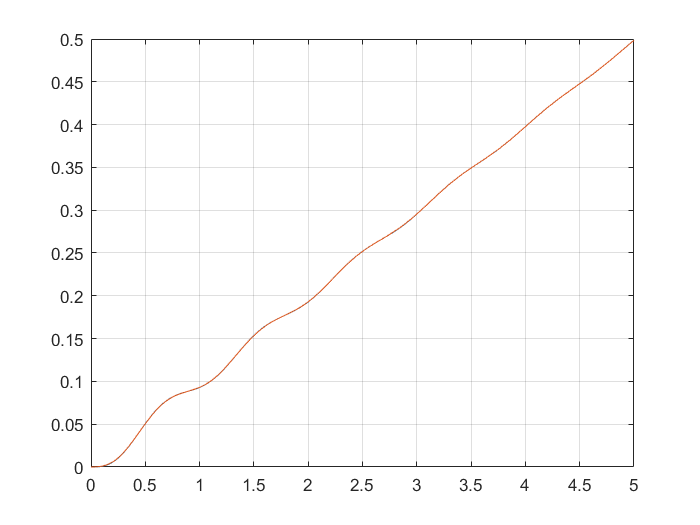


x1=-2e-3+0.1*t+[2e-3*cos(7.05*t)]*exp(-0.5*t)+[-2e-3*48.5/7.05*sin(7.05*t)]*exp(-0.5*t);

fplot(x,[0 5])
hold on
fplot(x1,[0 5])
grid on
hold off

## **Residual Method**

c_cr = 28.2843

F0 = 1

zeta = 0.0707

x_dot0 = 0.5000

X =
 
       0.75
  --------------
  (s^2 + s + 50)
 
Continuous-time zero/pole/gain model.



r =    0.0000 - 0.0532i
   0.0000 + 0.0532i


p =   -0.5000 + 7.0534i
  -0.5000 - 7.0534i


ans = 0.1063

phi = -1.5708

wn = 7.0711

$$x(t) = 5.31599999964237213134765625\,{\mathrm{e}}^{-0.5\,t}\,\cos\left(7.049999999813735485076904296875\,t-1.5700000000651925802230834960938\right)$$

$$y(t) = 0.074535599240334704518318176269531\,{\mathrm{e}}^{-2.2360679772682487964630126953125\,t}\,\sin\left(6.70820393227040767669677734375\,t\right)$$

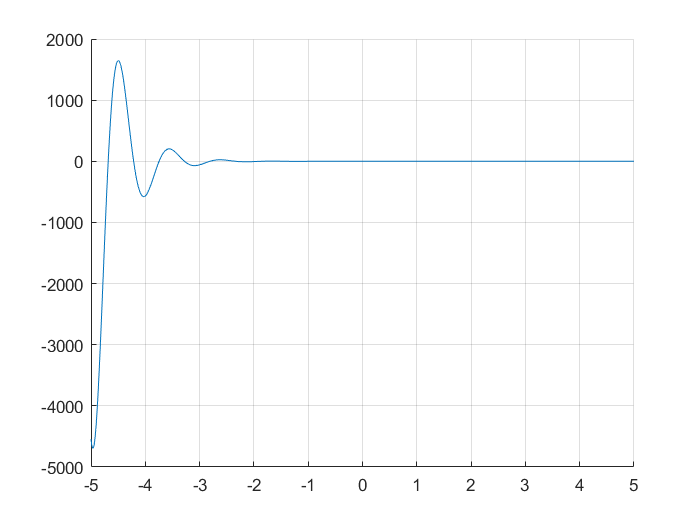



s= tf('s');

x_dot0=F0/m

% F(s)=F0 %because L(delta)=1

X=(F0)/(m*s^2+c*s+k);

X=zpk(minreal(X))


[N,D]=tfdata(X,'v');
[r,p]=residue(N,D)

2*abs(r(1))
phi=angle(r(1))

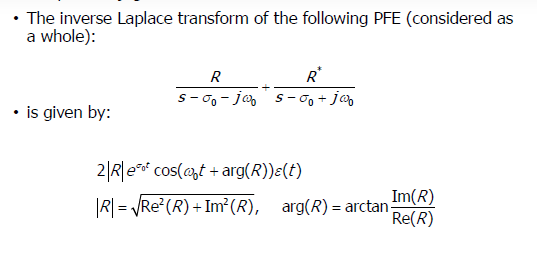

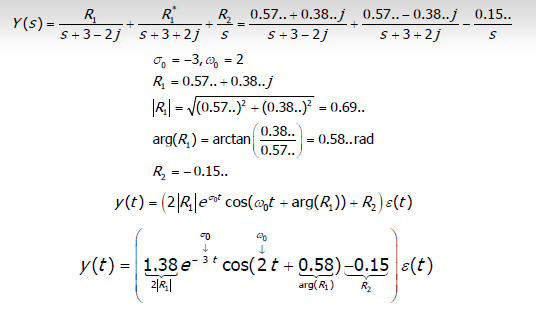

syms x t y

m=2;
k = 100;
c=2;
wn=sqrt(k/m);
F0=50;
zeta=sqrt(2/20);
wp=6.816;
wn=5*sqrt(2)

x(t)=vpa(5.316*exp(-0.5*t)*cos(7.05*t-1.57),2)
y(t)=vpa(exp(-zeta*wn*t)*1/(m*wn*sqrt(1-zeta^2))*sin(wn*sqrt(1-zeta^2)*t),2)
% fplot(x)
hold on
grid on
fplot(y)
hold off 






